# **Problema 4**

a) Implementați metoda lui Newton pentru rădăcini multiple.

Metoda lui Newton pentru **radacini simple **are rata de convergenta cel putin patratica, insa pentru radacini multiple, aceeasi metoda are rata de convergenta liniara.

Pentru a imbunatati rata de convergenta, putem folosi urmatoarea relatie de recurenta:


$$x_{k+1} =x_k -m\cdot \frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)},m=\textrm{ordin}\;\textrm{de}\;\textrm{multiplicitate}$$


Cu rata de convergenta: $\frac{m-1}{m}$

Daca insa m este necunoscut, il putem aproxima prin:


$$m\approx \frac{\ln |\frac{f\left(x_{k-1} \right)}{f\left(x_{k-2} \right)}|}{\ln |\frac{x_{k-1} -x_k }{x_{k-2} -x_k }|}$$


b) Se consideră ecuația $\frac{1}{2}x^2 +x+1-e^x =0$, pe [-1, 1]. Ce se întâmplă dacă se aplică metoda lui Newton cu x0 = 0?

Pentru $x_0 =0:f\left(x_0 \right)=0,f^{\prime } \left(x_0 \right)=0$. Avem caz de nedeterminare $\frac{0}{0}$.

c)  Remarcați convergența lentă, explicați fenomenul și găsiți un remediu.

Insa daca nu cunoastem ordinul de multiplicitate, convergenta este foarte lenta. Am putea empiric sa incercam sa ghicim ordinul de multiplicitate, astfel ajungand la o solutie. Din grafic se observa ca pe [-1, 1] avem o singura radacina, aceea fiind chiar x0 = 0. Convergenta este lenta nu are remediu in cazul acesta: avem o singura radacina, multiplicitatea 1 pe $\mathbb{R}$, insa dat fiind faptul ca avem caz de nedeterminare chiar din solutie, aproximarea initiala trebuie sa fie cat mai apropiata de 0, de ex $1*{10}^{-6}$.

d) Când este mai mic numărul de iterații: când se cunoaște multiplicitatea sau se estimează?

Numărul de iterații este același în ambele cazuri, având multiplicitatea 1.

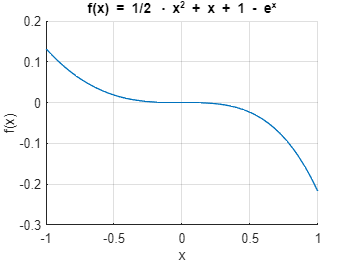

f = @(x) 0.5 .* x .^ 2 + x + 1 - exp(x);
df = @(x) x + 1 - exp(x);

figure; hold on;
fplot(f, [-1, 1])
title('f(x) = 1/2 \cdot x^2 + x + 1 - e^x');
grid on;
xlabel('x');
ylabel('f(x)');

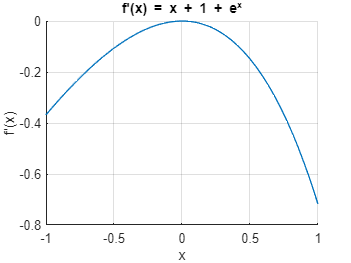


figure; hold on;
fplot(df, [-1, 1]);
title("f'(x) = x + 1 + e^x")
grid on;
xlabel('x');
ylabel("f'(x)")

[root0, iter0] = newton_multiple_roots(f, df, 0, 1);

fprintf("[x0 = 0] Root: %.16e | Iterations: %d\n", root0, iter0);

[x0 = 0] Root: NaN | Iterations: 9999


[root05, iter05] = newton_multiple_roots(f, df, 0.5, 1);
fprintf("[x0 = 0.5] Root: %.16e | Iterations: %d\n", root05, iter05);

[x0 = 0.5] Root: 9.3367371506939760e-06 | Iterations: 28


[root_near0, iter_near0] = newton_multiple_roots(f, df, 1e-7);
fprintf("[x0 = 1e-7] Root: %.16e | Iterations: %d\n", root_near0, iter_near0);

[x0 = 1e-7] Root: 9.9999999999999995e-08 | Iterations: 3


# **Problema 5**

Deduceți o formulă de cuadratură de forma


$$\int_{-1}^1 f\left(t\right)\mathrm{dt}=A_0 f\left(-1\right)+A_1 f\left(t_1 \right)+A_2 f\left(t_2 \right)+A_3 f\left(t_3 \right)+A_4 f\left(1\right)+R_f$$


care să aibă grad maxim de exactitate.

Intervalul și ponderea se potrivesc cu valorile pentru polinoamele ortogonale Legendre.

syms t k integer
assumeAlso(k >= 0)

f = t^k;
intf = int(f, t, -1, 1);
disp(intf);

$$\frac{{\left(-1\right)}^{k}+1}{k+1}$$


for i = 0:7
    I = vpa(subs(intf, k, i), 6);
    fprintf("k = %2d | I = %.6e\n", i, I);
end

k =  0 | I = 2.000000e+00
k =  1 | I = 0.000000e+00
k =  2 | I = 6.666667e-01
k =  3 | I = 0.000000e+00
k =  4 | I = 4.000000e-01
k =  5 | I = 0.000000e+00
k =  6 | I = 2.857143e-01
k =  7 | I = 0.000000e+00



$$\int_{-1}^1 t^k \mathrm{dt}=\frac{{\left(-1\right)}^k +1}{k+1}$$



$$\left\lbrack \begin{array}{ccccccc}
f\left(t\right) & f\left(-1\right) & f\left(t_1 \right) & f\left(t_2 \right) & f\left(t_3 \right) & f\left(1\right) & \int_{-1}^1 f\left(t\right)\mathrm{dt}\\
1 & 1 & 1 & 1 & 1 & 1 & 2\\
t & -1 & t_1  & t_2  & t_3  & 1 & 0\\
t^2  & 1 & t_1^2  & t_2^2  & t_3^2  & 1 & \frac{2}{3}\\
t^3  & -1 & t_1^3  & t_2^3  & t_3^3  & 1 & 0\\
t^4  & 1 & t_1^4  & t_2^4  & t_3^4  & 1 & \frac{2}{5}\\
t^5  & -1 & t_1^5  & t_2^5  & t_3^5  & 1 & 0\\
t^6  & 1 & t_1^6  & t_2^6  & t_3^6  & 1 & \frac{2}{7}\\
t^7  & -1 & t_1^7  & t_2^7  & t_3^7  & 1 & 0
\end{array}\right\rbrack$$


Rezulta sistemul:


$$\begin{array}{l}
f\left(t\right)=1:A_0 +A_1 +A_2 +A_3 +A_4 =2\\
f\left(t\right)=t:-A_0 +t_1 A_1 +t_2 A_2 +t_3 A_3 +A_4 =0\\
f\left(t\right)=t^2 :A_0 +t_1^2 A_1 +t_2^2 A_2 +t_3^2 A_3 +A_4 =\frac{2}{3}\\
f\left(t\right)=t^3 :-A_0 +t_1^3 A_1 +t_2^3 A_2 +t_3^3 A_3 +A_4 =0\\
f\left(t\right)=t^4 :A_0 +t_1^4 A_1 +t_2^4 A_2 +t_3^4 A_3 +A_4 =\frac{2}{5}\\
f\left(t\right)=t^5 :-A_0 +t_1^5 A_1 +t_2^5 A_2 +t_3^5 A_3 +A_4 =0\\
f\left(t\right)=t^6 :A_0 +t_1^6 A_1 +t_2^6 A_2 +t_3^6 A_3 +A_4 =\frac{2}{7}\\
f\left(t\right)=t^7 :-A_0 +t_1^7 A_1 +t_2^7 A_2 +t_3^7 A_3 +A_4 =0
\end{array}$$


syms A0 A1 A2 A3 A4 t1 t2 t3

eq1 = A0 + A1 + A2 + A3 + A4 == 2;
eq2 = -A0 + t1 * A1 + t2 * A2 + t3 * A3 + A4 == 0;
eq3 = A0 + t1^2 * A1 + t2^2 * A2 + t3^2 * A3 + A4 == 2/3;
eq4 = -A0 + t1^3 * A1 + t2^3 * A2 + t3^3 * A3 + A4 == 0;
eq5 = A0 + t1^4 * A1 + t2^4 * A2 + t3^4 * A3 + A4 == 2/5;
eq6 = -A0 + t1^5 * A1 + t2^5 * A2 + t3^5 * A3 + A4 == 0;
eq7 = A0 + t1^6 * A1 + t2^6 * A2 + t3^6 * A3 + A4 == 2/7;
eq8 = -A0 + t1^7 * A1 + t2^7 * A2 + t3^7 * A3 + A4 == 0;

solution = solve([eq1, eq2, eq3, eq4, eq5, eq6, eq7, eq8], [A0, A1, A2, A3, A4, t1, t2, t3]);
fields = fieldnames(solution);
for i = 1:length(fields)
    fprintf('%s = ', fields{i});
    disp(vpa(solution.(fields{i}), 6));
    fprintf('\n');
end

A0 = 

$$\left(\begin{array}{c} 0.1\\ 0.1\\ 0.1\\ 0.1\\ 0.1\\ 0.1 \end{array}\right)$$

A1 = 

$$\left(\begin{array}{c} 0.544444\\ 0.544444\\ 0.544444\\ 0.544444\\ 0.711111\\ 0.711111 \end{array}\right)$$

A2 = 

$$\left(\begin{array}{c} 0.544444\\ 0.544444\\ 0.711111\\ 0.711111\\ 0.544444\\ 0.544444 \end{array}\right)$$

A3 = 

$$\left(\begin{array}{c} 0.711111\\ 0.711111\\ 0.544444\\ 0.544444\\ 0.544444\\ 0.544444 \end{array}\right)$$

A4 = 

$$\left(\begin{array}{c} 0.1\\ 0.1\\ 0.1\\ 0.1\\ 0.1\\ 0.1 \end{array}\right)$$

t1 = 

$$\left(\begin{array}{c} 0.654654\\ -0.654654\\ 0.654654\\ -0.654654\\ 0\\ 0 \end{array}\right)$$

t2 = 

$$\left(\begin{array}{c} -0.654654\\ 0.654654\\ 0\\ 0\\ 0.654654\\ -0.654654 \end{array}\right)$$

t3 = 

$$\left(\begin{array}{c} 0\\ 0\\ -0.654654\\ 0.654654\\ -0.654654\\ 0.654654 \end{array}\right)$$

Rezulta solutiile:


$$A0 = \left(\begin{array}{c} 0.1\\ 0.1\\ 0.1\\ 0.1\\ 0.1\\ 0.1 \end{array}\right) \\
A1 = \left(\begin{array}{c} 0.544444\\ 0.544444\\ 0.544444\\ 0.544444\\ 0.711111\\ 0.711111 \end{array}\right) \\
A2 = \left(\begin{array}{c} 0.544444\\ 0.544444\\ 0.711111\\ 0.711111\\ 0.544444\\ 0.544444 \end{array}\right) \\
A3 = \left(\begin{array}{c} 0.711111\\ 0.711111\\ 0.544444\\ 0.544444\\ 0.544444\\ 0.544444 \end{array}\right) \\
A4 = \left(\begin{array}{c} 0.1\\ 0.1\\ 0.1\\ 0.1\\ 0.1\\ 0.1 \end{array}\right) \\
t1 = \left(\begin{array}{c} 0.654654\\ -0.654654\\ 0.654654\\ -0.654654\\ 0\\ 0 \end{array}\right) \\
t2 = \left(\begin{array}{c} -0.654654\\ 0.654654\\ 0\\ 0\\ 0.654654\\ -0.654654 \end{array}\right) \\
t3 = \left(\begin{array}{c} 0\\ 0\\ -0.654654\\ 0.654654\\ -0.654654\\ 0.654654 \end{array}\right) \\$$


Alegem prima solutie, adica:


$$\int_{-1}^1 f\left(t\right)\mathrm{dt}=\;0\ldotp 1+0\ldotp 544444\cdot f\left(0\ldotp 654654\right)+\;0\ldotp 544444\cdot f\left(-0\ldotp 654654\right)+0\ldotp 711111\cdot f\left(0\right)+0\ldotp 1+R\left(f\right)$$



$$\begin{array}{l}
R\left(f\right)=\frac{f^{\left(8\right)} \left(\xi \right)}{8!}\cdot \int_{-1}^1 \omega \left(t\right)\mathrm{dt},\mathrm{unde}\;\omega \left(t\right)=\left(t+1\right)\left(t-t_1 \right)\left(t-t_2 \right)\left(t-t_3 \right)\left(t-1\right),\xi \in \left(-1,1\right)\\
\int_{-1}^1 \omega \left(t\right)\mathrm{dt}=\frac{4t_1 +4t_2 +4t_3 +20t_1 t_2 t_3 }{15},\mathrm{iar}\;\mathrm{cu}\;\mathrm{valorile}\;\mathrm{aproximate}\Rightarrow \omega \left(t\right)=0\Rightarrow R\left(f\right)=0
\end{array}$$


syms t t1 t2 t3

omega = (t+1)*(t-t1)*(t-t2)*(t-t3)*(t-1);
int_omega = int(omega, t, -1, 1);
fprintf("I_omega = ");

I_omega = 

disp(int_omega);

$$\frac{4\,t_{1}}{15}+\frac{4\,t_{2}}{15}+\frac{4\,t_{3}}{15}+\frac{4\,t_{1}\,t_{2}\,t_{3}}{3}$$

fprintf("\n");

omega_known = (t+1)*(t-0.69622)*(t+0.69622)*(t-0)*(t-1);
int_omega_known = int(omega_known, t, -1, 1);
fprintf("I_omega = ");

I_omega = 

disp(vpa(int_omega_known, 6));

$$0.0$$

fprintf("\n");

Rezulta formula de cuadratura:


$$\int_{-1}^1 f\left(t\right)\mathrm{dt}=\;0\ldotp 1+0\ldotp 544444\cdot f\left(0\ldotp 654654\right)+\;0\ldotp 544444\cdot f\left(-0\ldotp 654654\right)+0\ldotp 711111\cdot f\left(0\right)+0\ldotp 1$$


# **Problema 6**

Șirul $x_n ={10}^{-n^2 } \;\mathrm{converge}\;\mathrm{către}\;0\;\mathrm{când}\;n\to \infty$. Arătați că converge superliniar. Ce se poate spune despre ordinul de convergență?

Pentru o metoda iterativa care converge la o valoare $L$, un sir $\left(x_k \right)$ are ordinul de convergenta $q\ge 1$ si rata de convergenta $\mu$ daca:

$\lim_{k\to \infty } \frac{|x_{k+1} -L|}{|x_k -L|^q }=\mu$. Sirul converge superliniar daca $\mu \in \left(1,2\right)$.

Sirul nostru $x_n ={10}^{-n^2 }$ are ordinul de convergenta $q$ daca $\exists \;C>0$ a.i.:


$$\begin{array}{l}
x_{n+1} \approx C\cdot x_n^q \Leftrightarrow \ln \left(x_{n+1} \right)\approx \ln \left(C\right)+q\cdot \ln \left(x_n \right)\\
x_n ={10}^{-n^2 } \Leftrightarrow \ln \left(x_n \right)=-n^2 \cdot \ln \left(10\right)\\
x_{n+1} ={10}^{-{\left(n+1\right)}^2 } \Leftrightarrow \ln \left(x_{n+1} \right)=-{\left(n+1\right)}^2 \cdot \ln \left(10\right)\\
\frac{\ln \left(x_{n+1} \right)}{\ln \left(x_n \right)}=\frac{{\left(n+1\right)}^2 }{n^2 }=\frac{n^2 {\left(1+\frac{1}{n}\right)}^2 }{n^2 }={\left(1+\frac{1}{n}\right)}^2 >1
\end{array}$$


Astfel: $\ln \left(x_{n+1} \right)=\ln \left(1\right)+{\left(1+\frac{1}{n}\right)}^2 \ln \left(x_n \right)\Rightarrow x_{n+1} =1\cdot x_n^{{\left(1+\frac{1}{n}\right)}^2 }$. Ordinul de convergenta este $q={\left(1+\frac{1}{n}\right)}^2 ,n>0$.

Rata de convergenta este > 1:


$$\lim_{n\to \infty } \frac{x_{n+1} }{x_n }=\lim_{n\to \infty } \frac{{10}^{-n^2 \cdot {\left(1+\frac{1}{n}\right)}^2 } }{{10}^{-n^2 } }=\lim_{n\to \infty } {10}^{-2n-1} =\lim_{n\to \infty } \frac{1}{{10}^{2n+1} }=\frac{1}{{10}^{\infty } }=0$$
 

Limita cand n tinde la infinit este 0, de unde rezulta faptul ca rata de convergenta este superliniara.

function [root, iter] = newton_multiple_roots(f, df, x0, m, tol, max_iter)
    %% NEWTOK_MULTIPLE_ROOTS - Newton-Raphson method adapted for multiple roots
    %
    %  Inputs:
    %
    %  f        - function to approximate;
    %  df       - first derivative of the function to approximate;
    %  x0       - initial guess;
    %  tol      - acceptable error between iterations;
    %  max_iter - maximum number of iterations
    %
    %  Outputs
    %
    %  root     - the approximated root;
    %  iter     - the number of iterations took to approximate the root;
    %
    %  Error: if the number of iterations is exceeded.
    known_m = true;

    if nargin < 3
        x0 = 0;
    end
    if nargin < 4
        known_m = false;
    end
    if nargin < 5
        tol = 1e-6;
    end
    if nargin < 6
        max_iter = 10000;
    end

    % Keeping track of 3 iterations: x_{k-2}, x_{k-1}, x_k
    x = zeros(1, max_iter + 2);
    fx = zeros(1, max_iter + 2);
    x(1) = x0;
    fx(1) = f(x0);

    % First step, with classic Newton-Raphson
    x(2) = x(1) - fx(1) / df(x(1));
    fx(2) = f(x(2));

    % Second step, again with classic Newton-Raphson
    x(3) = x(2) - fx(2) / df(x(2));
    fx(3) = f(x(3));

    for i = 4:max_iter+1
        % Estimating the multiplicity of the roots, if it is not known
        if ~known_m 
            num = log(abs(fx(i-1) / fx(i-2)));
            den = log(abs((x(i-1) - x(i-2)) / (x(i-2) - x(i-3))));
            if isnan(num) || isnan(den) || isinf(num) || isinf(den) || den == 0
                m = 1;
            else
                m = num / den;
            end
        end

        % Computing the iteration
        x(i) = x(i - 1) - m * fx(i-1) / df(x(i-1));
        fx(i) = f(x(i));

        % Checking if the approximation is acceptable
        if abs(x(i) - x(i-1)) < tol
            root = x(i);
            iter = i - 1;
            return;
        end
    end

    root = x(max_iter - 1);
    iter = max_iter - 1;
    warning('Approximation did not converge in %d maximum iterations', max_iter);
end